## Problem 3.1

#### Case: n < p

n = 10; % number of samples
p = 10000; % number of features

% Generate random data for matrix X (centered)
X = randn(n, p);

Y = X'* X;
disp("If n <p:")

If n <p:


disp("Size of the square matrix:");

Size of the square matrix:


disp(size(Y));

       10000       10000



disp("Rank of the square matrix");

Rank of the square matrix


disp(rank(Y));

    10



#### Case n > p:

disp("If n > p:");

If n > p:


n = 1000; % number of samples
p = 100; % number of features

% Generate random data for matrix X (centered)
X = randn(n, p);

Y = X'*X;
disp("Size of the square matrix:");

Size of the square matrix:


disp(size(Y));

   100   100



disp("Rank of the square matrix");

Rank of the square matrix


disp(rank(Y));

   100



Given that the rank of the matrix is less than its size, and the number of features *p* exceeds the number of samples *n*, the resulting matrix is singular and therefore non-invertible. Consequently, this scenario precludes the viability of a closed-form solution.

## PROBLEM 3.2

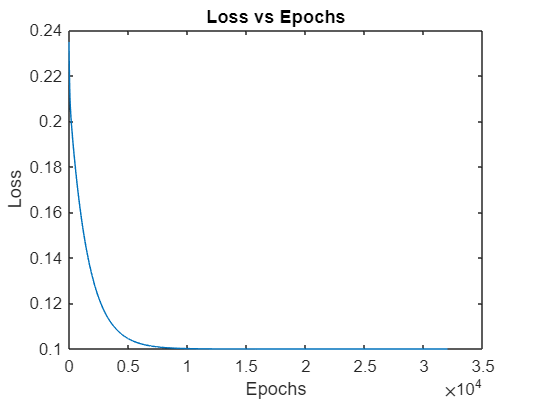

% Given matrix A, target vector y, learning rate, and initial weights
A = [1, 2, 4; 1, 3, 5; 1, 7, 7; 1, 8, 9];
y = [1; 2; 3; 4];

% Compute the maximum singular value of A
max_singular_value = max(svd(A' * A));

% Set learning rate as the inverse of the max singular value
learningRate = 1 / max_singular_value;
weights = zeros(size(A, 2), 1);

% Initialize a vector to track loss values
lossHistory = zeros(1, 32000);

% Vanilla Gradient Descent (32k iterations)
for epoch = 1:32000
    gradient = A' * (A * weights - y);
    weights = weights - learningRate * gradient;
    lossHistory(epoch) = norm(A * weights - y)^2;
end

% Calculate the convergence factor
convergenceFactor = lossHistory(2:end) ./ lossHistory(1:end-1);

% Plot Loss vs Epochs
plot(lossHistory);
title('Loss vs Epochs');
xlabel('Epochs');
ylabel('Loss');

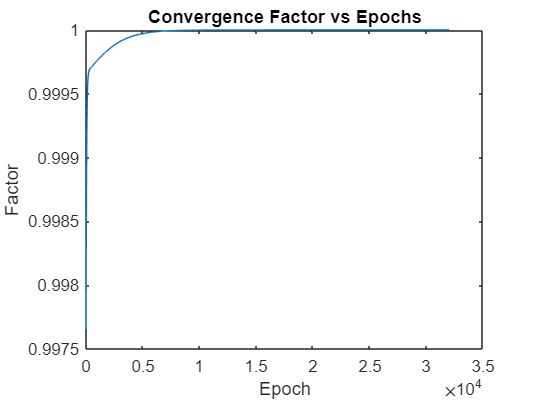


% Plot Convergence Factor vs Epochs
figure;
plot(convergenceFactor);
title('Convergence Factor vs Epochs');
xlabel('Epoch');
ylabel('Factor');


% Closed form solution for verification
weightsClosedForm = pinv(A' * A) * A' * y;
display(weightsClosedForm);

weightsClosedForm =    -1.0000
    0.0333
    0.5333


display(weights);

weights =    -1.0000
    0.0333
    0.5333


From analyzing the weight matrices, it's evident that the Gradient Descent approach achieves the optimal solution, exhibiting nearly linear convergence with the specified learning rate.

## PROBLEM 3.3

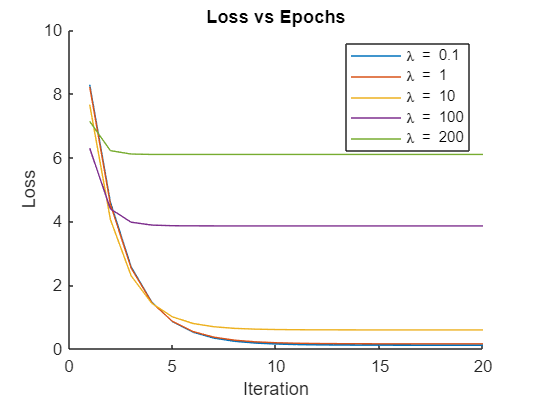

% Define the matrix A and vector y
A = [1, 2, 4; 1, 3, 5; 1, 7, 7; 1, 8, 9];
y = [1; 2; 3; 4];

% Define a range of λ values
lambda_values = [0.1, 1, 10, 100, 200];

% Define the number of iterations
num_iterations = 20;

% Initialize variables to store losses
losses = zeros(length(lambda_values), num_iterations);

% Perform gradient descent for each λ
for k = 1:length(lambda_values)
    lambda = lambda_values(k);
    alpha = 1 / (max(max(A' * A)) + lambda_values(k));

    % Initialize θ0 to [0; 0; 0]
    theta = [0; 0; 0];
    for iteration = 1:num_iterations
        % Compute the gradient for ridge regression
        gradient = -A' * (y - A * theta) + lambda * theta;
        
        % Update θ using the gradient and learning rate
        theta = theta - alpha * gradient;
        
        % Calculate the cost (ridge regression loss)
        loss = (1 / (2 )) * norm(A * theta - y)^2 + (theta' ...
            * theta) * (lambda / 2);
        % Store the loss
        losses(k, iteration) = loss;
    end
end

% Plot the loss curves for different λ values
figure;
hold on;
for k = 1:length(lambda_values)
    semilogy(1:num_iterations, losses(k, :), 'DisplayName', ...
        ['\lambda = ', num2str(lambda_values(k))]);
end

hold off;
xlabel('Iteration');
ylabel('Loss');
title("Loss vs Epochs");
legend;


%Verifying the results obtained from closed form solution
weights2 = pinv(A'*A + lambda_values(5)*eye(size(A, 2)))*A'*y;

To verify, let us compare the closed form weights and weights

display(weights2);

weights2 =     0.0195
    0.1231
    0.1423


display(weights);

weights =    -1.0000
    0.0333
    0.5333
